clc; clear all; close all;

% Constantes
m = 1.79;      g= 9.77412;
Ix = 0.03;     Iy = 0.03;
Iz = 0.04;     T = 0.01;

#### Representación en Espacio de Estados

Am = [0 0 0 0  0 0 1 0 0 0 0 0 ;
      0 0 0 0  0 0 0 1 0 0 0 0 ;
      0 0 0 0  0 0 0 0 1 0 0 0 ;
      0 0 0 0  0 0 0 0 0 1 0 0 ;
      0 0 0 0  0 0 0 0 0 0 1 0 ;
      0 0 0 0  0 0 0 0 0 0 0 1 ;
      0 0 0 0 -g 0 0 0 0 0 0 0 ;
      0 0 0 g  0 0 0 0 0 0 0 0 ;
      0 0 0 0  0 0 0 0 0 0 0 0 ;
      0 0 0 0  0 0 0 0 0 0 0 0 ;
      0 0 0 0  0 0 0 0 0 0 0 0 ;
      0 0 0 0  0 0 0 0 0 0 0 0 ];

Bm = [0 0 0 0;
      0 0 0 0;
      0 0 0 0;
      0 0 0 0;
      0 0 0 0;
      0 0 0 0;
      0 0 0 0;
      0 0 0 0;
      1/m 0 0 0;
      0 1/Ix 0 0;
      0 0 -1/Iy 0;
      0 0 0 -1/Iz];

Cm = [1 0 0 0 0 0 0 0 0 0 0 0 ;
      0 1 0 0 0 0 0 0 0 0 0 0 ;
      0 0 1 0 0 0 0 0 0 0 0 0 ;
      0 0 0 0 0 1 0 0 0 0 0 0 ];

Dm = zeros(4,4);
    
[num1,den1] = ss2tf(Am,Bm,Cm,Dm,1);
[num2,den2] = ss2tf(Am,Bm,Cm,Dm,2);
[num3,den3] = ss2tf(Am,Bm,Cm,Dm,3);
[num4,den4] = ss2tf(Am,Bm,Cm,Dm,4);

num1_ = num1(3,:)

num1_ =          0         0    0.5587         0         0         0         0         0         0         0         0         0         0


num2_ = num2(2,:)

num2_ =          0         0         0         0  325.8040         0         0         0         0         0         0         0         0


num3_ = num3(1,:)

num3_ =          0         0         0         0  325.8040         0         0         0         0         0         0         0         0


num4_ = num4(4,:)

num4_ =      0     0   -25     0     0     0     0     0     0     0     0     0     0



%Gtf1 = tf(num1_,den1)
Gtf1 = tf(0.5587,[1 0 0])

Gtf1 =
 
  0.5587
  ------
   s^2
 
Continuous-time transfer function.




%Gtf2 = tf(num2_,den2)
Gtf2 = tf(33.33,[1 0 0])

Gtf2 =
 
  33.33
  -----
   s^2
 
Continuous-time transfer function.




%Gtf3 = tf(num3_,den3)
Gtf3 = tf(-33.33,[1 0 0])

Gtf3 =
 
  -33.33
  ------
   s^2
 
Continuous-time transfer function.




%Gtf4 = tf(num4_,den4)
%Gtf4 = tf(-num4(4,:),den4)
Gtf4 = tf(25,[1 0 0])

Gtf4 =
 
  25
  ---
  s^2
 
Continuous-time transfer function.



#### Modelo Aumentado

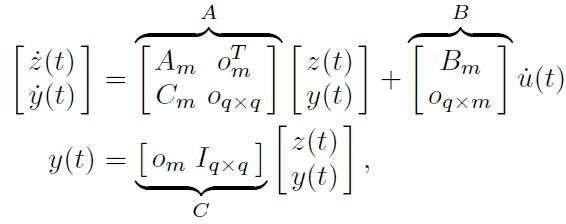

[m1,n1]=size(Cm);
[n1,n_in]=size(Bm);

A=zeros(n1+m1,n1+m1);
A(1:n1,1:n1)=Am;
A(n1+1:n1+m1,1:n1)=Cm;

B=zeros(n1+m1,n_in);
B(1:n1,:)=Bm;

C=zeros(m1,n1+m1);
C(:,n1+1:n1+m1)=eye(m1,m1);

# MPC sin Restricciones con Qball

#### Parámetros de Laguerre para cada entrada

**Q:** peso sobre las variables de estado

**R:** peso sobre las variables de entrada

Q=C'*C;
R=0.1*eye(n_in,n_in);

p1=20;
p2=20;
p3=20;
p4=20;

% 2 --> inestable
% 20,20,30,40 --> inestable
% 40 --> Estable por un tiempo
% 40,40,60,60 --> Estable por un tiempo
% 100 --> inestable
% 20,20,60,60 --> inestable

N1=10;
N2=10;
N3=10;
N4=10;

p=[p1 p2 p3 p4];
N=[N1 N2 N3 N4];
Tp=10; % Horizonte de predicción
% Tp = 5,50 --> Inestable, Matriz singular

[Ap1,L1]=lagc(p1,N1);
[Ap2,L2]=lagc(p2,N2);
[Ap3,L3]=lagc(p3,N3);
[Ap4,L4]=lagc(p4,N4); 

#### Gráfica de las Funciones de Laguerre

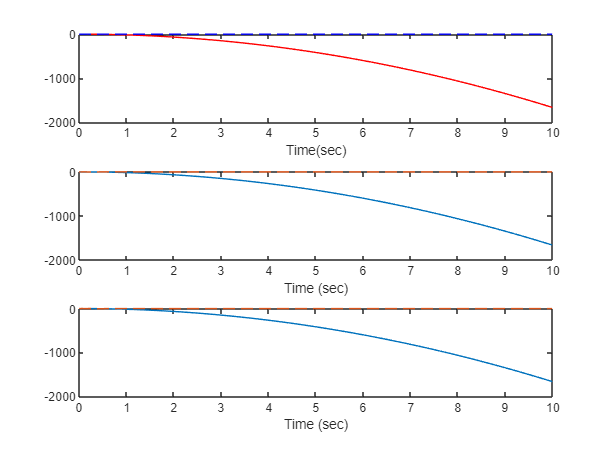

delta_t=0.01;
N_sample=Tp/delta_t;
t=0:delta_t:(N_sample-1)*delta_t;
for i=1:N_sample
    L(:,i)=expm(Ap1*t(i))*L1;
end

h_t=step(-33.33,[1 0 0],t)';
%h_t=impulse(-33.33,[1 1 1],t)';

hL_1=L(1,:).*h_t;
c1=inte(hL_1,delta_t);              

hL_2=L(2,:).*h_t;
c2=inte(hL_2,delta_t);

hL_3=L(3,:).*h_t;
c3=inte(hL_3,delta_t);

hL_4=L(4,:).*h_t;
c4=inte(hL_4,delta_t);

hL_5=L(5,:).*h_t;
c5=inte(hL_5,delta_t);

hL_6=L(6,:).*h_t;
c6=inte(hL_6,delta_t);

h_model2=c1*L(1,:)+c2*L(2,:);
h_model4=c1*L(1,:)+c2*L(2,:)+c3*L(3,:)+c4*L(4,:);
h_model6=c1*L(1,:)+c2*L(2,:)+c3*L(3,:)+c4*L(4,:)+c5*L(5,:)+c6*L(6,:);

figure
subplot(311)
plot(t,h_t,'r',t,h_model2,'b--');
xlabel('Time(sec)')

subplot(312)
plot(t,h_t,t,h_model4,'--');
xlabel('Time (sec)')

subplot(313)
plot(t,h_t,t,h_model6,'--');
xlabel('Time (sec)')

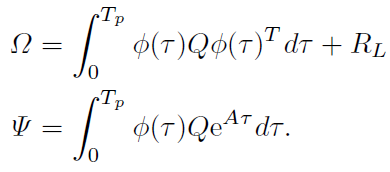         

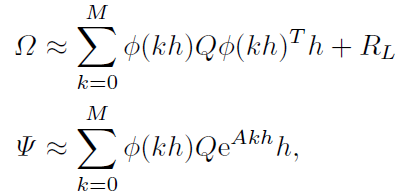

[Omega,Psi]=cmpc(A,B,p,N,Tp,Q,R);

Lzerot=zeros(n_in,N1+N2+N3+N4);
Lzerot(1,1:N1)=L1';
Lzerot(2,N1+1:N1+N2)=L2';
Lzerot(3,N1+N2+1:N1+N2+N3)=L3';
Lzerot(4,N1+N2+N3+1:N1+N2+N3+N4)=L4';

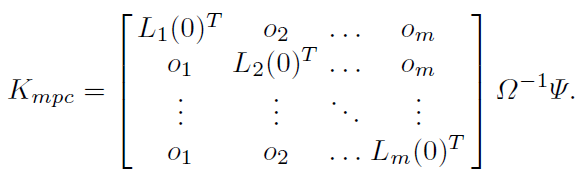

K_mpc=Lzerot*(Omega\Psi);
Acl=A-B*K_mpc;
eig(Acl);

El programa anterior produce el control predictivo del modelo de tiempo continuo usando funciones de Laguerre. La ganancia de control de retroalimentación de estado es $K$ y la matriz del sistema de bucle cerrado es $Acl$.

**lqr():** Regulador Lineal Cuadrático (LQ) de feedback de estados para un sistema de espacio de estados de tiempo continuo.

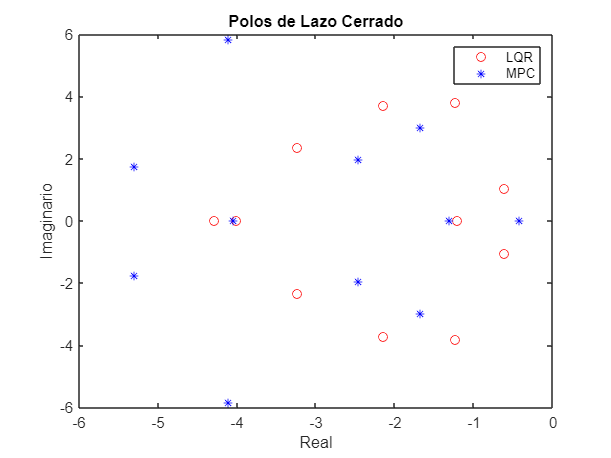

[K,S,E]=lqr(A,B,Q,R);

figure(2)
plot(E,'ro')        % Polos del LQR

hold on
plot(eig(Acl),'b*') % Polos del MPC

xlabel('Real')
ylabel('Imaginario')
title('Polos de Lazo Cerrado')
legend('LQR','MPC')

#### Simulación en Lazo Cerrado

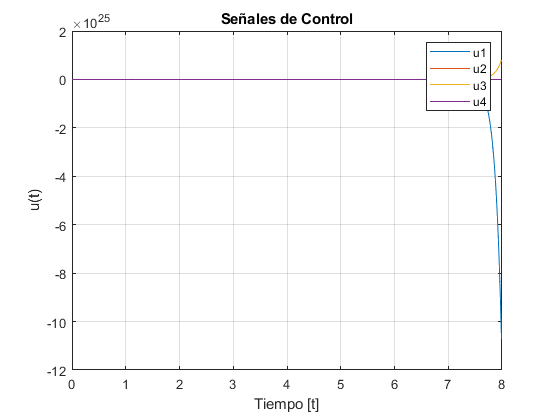

K_ob = K_mpc';
xm=zeros(n1,1);
u0=zeros(n_in,1);
y0=zeros(m1,1);
N_sim=8e2;

h=0.01;
r1=ones(1,N_sim+200);
r2=zeros(1,N_sim+200);
r3=zeros(1,N_sim+200);
r4=zeros(1,N_sim+200);
sp=[r1;r2;r3;r4];

[u,y,udot,t]=cssimuob(xm,u0,y0,sp,Am,Bm,Cm,A,B,C,N_sim,Omega,Psi,K_ob,Lzerot,h);

figure(3)
plot(t,u)
grid on
xlabel('Tiempo [t]')
ylabel('u(t)')
title('Señales de Control')
legend('u1','u2','u3','u4')

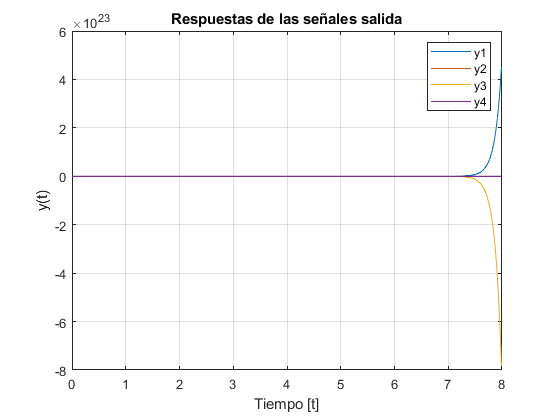


figure(4)
plot(t,y)
grid on
xlabel('Tiempo [t]')
ylabel('y(t)')
title('Respuestas de las señales salida')
legend('y1','y2','y3','y4')

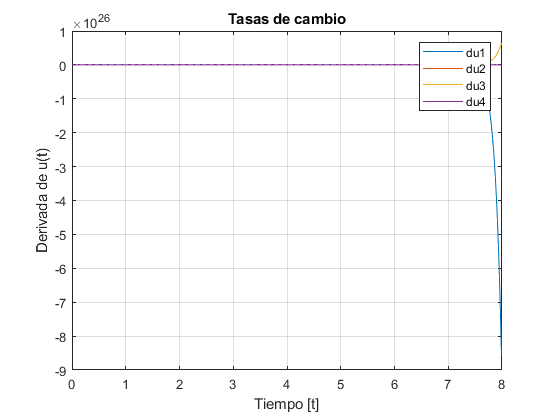


figure(5)
plot(t,udot)
grid on
xlabel('Tiempo [t]')
ylabel('Derivada de u(t)')
title('Tasas de cambio')
legend('du1','du2','du3','du4')

# MPC con Restricciones con Qball

#### Se definen las restricciones, solo en la primera muestra

tau = 0.1;
[Md,Lzerot]=Mder(p,N,n_in,tau);
[Mu,Mu1]=Mucon(p,N,n_in,h,tau);
M=[Mu;-Mu;Lzerot;-Lzerot];

#### Restricciones

u_max=[3;3;3;3];
u_min=[-3;-3;-3;-3];
Deltau_max=[0.4;0.4;0.4;0.4];
Deltau_min=[-0.4;-0.4;-0.4;-0.4];

u=zeros(n_in,1);
y=zeros(m1,1);

sp1=ones(1,N_sim);
sp2=zeros(1,N_sim);
sp3=zeros(1,N_sim);
sp4=zeros(1,N_sim);

sp=[sp1;sp2;sp3;sp4];

#### Simulación en Lazo Cerrado

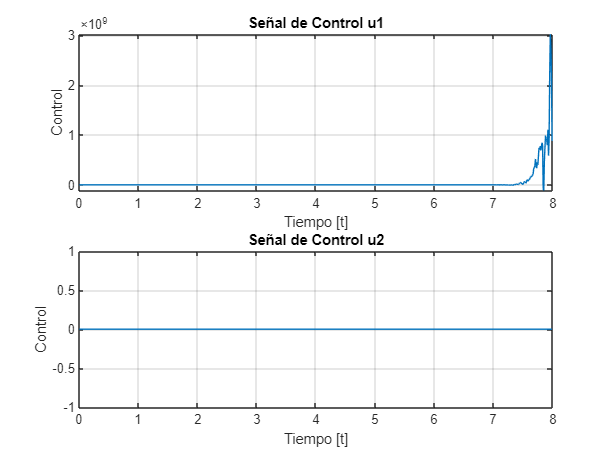

[u1,y1,udot1,t]=cssimucon(xm,u,y,sp,Am,Bm,Cm,A,B,C,N_sim,Omega,Psi,K_ob,Lzerot,h,M,u_max,u_min,Deltau_max,Deltau_min);

figure(6)

subplot(2,1,1)
plot(t,u1(1,:))
grid on
xlabel('Tiempo [t]')
ylabel('Control')
title('Señal de Control u1')

subplot(2,1,2)
plot(t,u1(2,:))
grid on
xlabel('Tiempo [t]')
ylabel('Control')
title('Señal de Control u2')

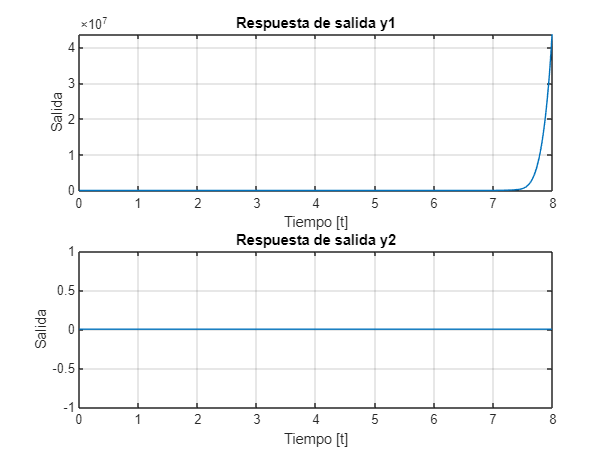




figure(7)

subplot(2,1,1)
plot(t,y1(1,:))
grid on
xlabel('Tiempo [t]')
ylabel('Salida')
title('Respuesta de salida y1')

subplot(2,1,2)
plot(t,y1(2,:))
grid on
xlabel('Tiempo [t]')
ylabel('Salida')
title('Respuesta de salida y2')

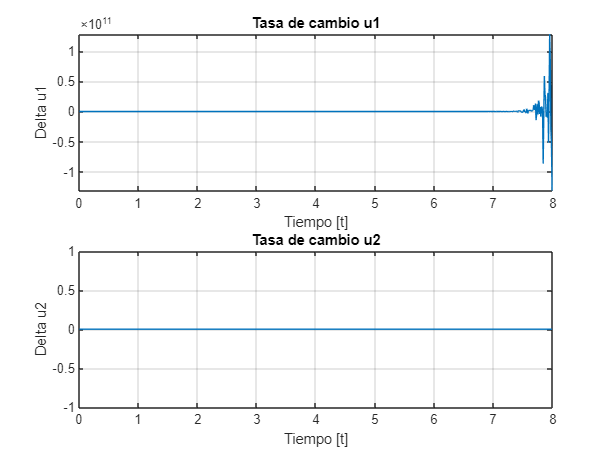



figure(8)

subplot(2,1,1)
plot(t,udot1(1,:))
grid on
xlabel('Tiempo [t]')
ylabel('Delta u1')
title('Tasa de cambio u1')

subplot(2,1,2)
plot(t,udot1(2,:))
grid on
xlabel('Tiempo [t]')
ylabel('Delta u2')
title('Tasa de cambio u2')